
$$Q=mc\Delta T$$


여기서:

- Q: 제거해야 할 열량 (kJ)

- m: 물의 질량 (kg) (물의 밀도를 1 kg/L로 가정)

- c: 물의 비열 $(4.185 \, \text{kJ/kg\cdot K})$

- $\Delta T$: 온도 변화 $(T_{final} - T_{initial}l)$

**주어진 수치**

- $m = 20 \, \text{kg}$ (물 20L)

- 
$$c = 4.185 \, \text{kJ/kg\cdot K}$$


- 
$$T_{initial} = 80^\circ\text{C}$$


- 
$$T_{final} = 25^\circ\text{C}$$


 % 주어진 값들
m = 20; % 물의 질량 (kg)
c = 4.185; % 물의 비열 (kJ/kg·K)
T_initial = 80; % 초기 온도 (°C)
T_final = 25; % 최종 온도 (°C)

% 온도 변화에 따른 열량 계산
Delta_T = T_final - T_initial; % 온도 변화 (°C)
Q = m * c * Delta_T; % 열량 (kJ)

% 결과 출력
fprintf('제거해야 할 열량 Q = %.2f kJ\n', Q);

제거해야 할 열량 Q = -4603.50 kJ


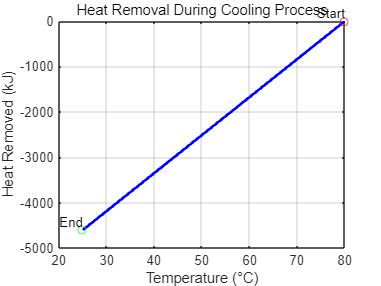


% 시각화를 위한 데이터
T_range = linspace(T_initial, T_final, 100); % 온도 변화 범위
Q_values = m * c * (T_range - T_initial); % 각 온도에 따른 열량 변화

% 2D 그래프 그리기
figure;
plot(T_range, Q_values, 'b-', 'LineWidth', 2);
xlabel('Temperature (°C)');
ylabel('Heat Removed (kJ)');
title('Heat Removal During Cooling Process');
grid on;
hold on;

% 시작 및 끝점 표시
scatter(T_initial, 0, 'ro');
scatter(T_final, Q, 'go');
text(T_initial, 0, ' Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(T_final, Q, ' End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

hold off;

**주어진 수치**

- 금속 질량 $(m_1)$ = 10 kg

- 금속 초기 온도 $(T_{m1}) = 70\degree C$

- 금속 최종 온도 $(T_f) = 40\degree C$

- 금속의 비열 $(C_1) = ?$

- 물의 질량 $(m_2) = 6 kg$

- 물의 초기 온도 $(T_{m2}) = 20\degree C$

- 물의 최종 온도 $(T_f) = 40\degree C$

- 물의 비열 $(C_2) = 1 kcal/kg\cdot \degree C$

**열 교환 공식**

- 금속이 방출한 열량 $Q_1$:


$$Q_1 = m_1 C_1 (T_{m1} - T_f)$$


- 물이 흡수한 열량$Q_2$�:


$$Q_2 = m_2 C_2 (T_f - T_{m2})$$


- 열 평형에서:


$$Q_1 = Q_2$$



$$m_1 C_1 (T_{m1} - T_f) = m_2 C_2 (T_f - T_{m2})$$


% 주어진 값들
m1 = 10; % 금속의 질량 (kg)
Tm1_initial = 70; % 금속의 초기 온도 (°C)
Tf = 40; % 최종 평형 온도 (°C)

m2 = 6; % 물의 질량 (kg)
Tm2_initial = 20; % 물의 초기 온도 (°C)
C2 = 1; % 물의 비열 (kcal/kg·°C)

% 열 평형 방정식 설정
% m1 * C1 * (Tm1_initial - Tf) = m2 * C2 * (Tf - Tm2_initial)
% C1 계산
Q2 = m2 * C2 * (Tf - Tm2_initial);
C1 = Q2 / (m1 * (Tm1_initial - Tf));

% 결과 출력
fprintf('금속의 비열 C1 = %.2f kcal/kg·°C\n', C1);

금속의 비열 C1 = 0.40 kcal/kg·°C


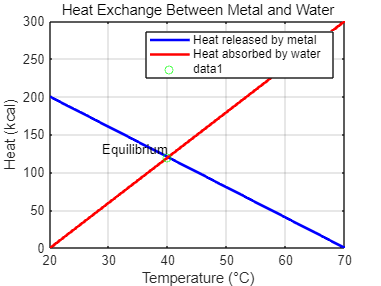


% 시각화를 위한 데이터
temperature_range = linspace(Tm2_initial, Tm1_initial, 100); % 온도 변화 범위
Q1_values = m1 * C1 * (Tm1_initial - temperature_range); % 금속이 방출한 열량
Q2_values = m2 * C2 * (temperature_range - Tm2_initial); % 물이 흡수한 열량

% 2D 그래프 그리기
figure;
plot(temperature_range, Q1_values, 'b-', 'LineWidth', 2);
hold on;
plot(temperature_range, Q2_values, 'r-', 'LineWidth', 2);
xlabel('Temperature (°C)');
ylabel('Heat (kcal)');
title('Heat Exchange Between Metal and Water');
legend('Heat released by metal', 'Heat absorbed by water');
grid on;

% 평형 상태 표시
scatter(Tf, Q2, 'go');
text(Tf, Q2, ' Equilibrium', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

hold off;

**주어진 조건**

- 물질 A의 온도 $(T_A) = 40\degree C$

- 물질 B의 온도 $(T_B) = 80\degree C$

- 물질 C의 온도 $(T_C) = 25\degree C$

- A와 B의 혼합 열평형 온도 $(T_{AB}) = 58\degree C$

- A와 C의 혼합 열평형 온도 $(T_{AC}) = 32\degree C$

**목표**

- 물질 B와 C를 동일한 질량으로 혼합할 때의 열평형 온도$(T_{BC})$를 구하는 것.

**계산 과정**

- 물질 A와 B의 비열비 $\frac{C_A}{C_B}$:


$$\frac{C_A}{C_B} = \frac{T_B - T_{AB}}{T_{AB} - T_A}$$



$$\frac{C_A}{C_B} = \frac{80 - 58}{58 - 40} = 1.222$$


- 물질 A와 C의 비열비 $\frac{C_A}{C_C}$��:


$$\frac{C_A}{C_C} = \frac{T_C - T_{AC}}{T_{AC} - T_A}
$$



$$\frac{C_A}{C_C} = \frac{32 - 25}{40 - 32} = 0.875$$


- 물질 B와 C의 비열비 $\frac{C_B}{C_C}$:��


$$\frac{C_B}{C_C} = \frac{C_B}{C_A} \times \frac{C_A}{C_C} = \frac{1}{1.222} \times 0.875$$


- 물질 B와 C의 혼합 열평형 온도 $T_{BC}$�:

$T_{BC} = \frac{C_B T_B + C_C T_C}{C_B + C_C}$��

% 주어진 값들
T_B = 80; % 물질 B의 온도 (°C)
T_C = 25; % 물질 C의 온도 (°C)

% 물질 B와 C의 비열비
C_B_div_C_C = 0.716;

% 방정식을 풀기 위한 심볼릭 변수 정의
syms T_BC_sym
% 방정식 설정
T_BC_eqn = (T_BC_sym - T_C) / (T_B - T_BC_sym) == C_B_div_C_C;

% 방정식 풀기 (범위 지정)
T_BC_solution = vpasolve(T_BC_eqn, T_BC_sym, [T_C, T_B]);

% 결과 출력
fprintf('물질 B와 C의 혼합 열평형 온도 T_BC = %.2f°C\n', T_BC_solution);

물질 B와 C의 혼합 열평형 온도 T_BC = 47.95°C


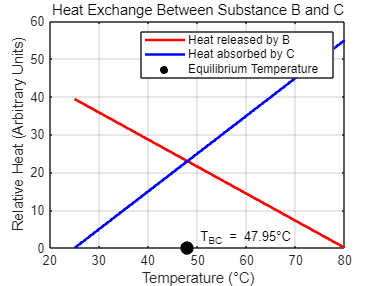


% 시각화를 위한 데이터 생성
% 물질 B와 C의 온도 변화
T_range = linspace(T_C, T_B, 100); % 온도 범위 생성

% 물질 B와 C의 열량 변화 가정 (임의의 선형 비율)
Q_B = C_B_div_C_C * (T_B - T_range); % B의 열량 변화
Q_C = (T_range - T_C); % C의 열량 변화

% 2D 그래프 그리기
figure;
plot(T_range, Q_B, 'r-', 'LineWidth', 2); % 물질 B의 열량 변화
hold on;
plot(T_range, Q_C, 'b-', 'LineWidth', 2); % 물질 C의 열량 변화

% 열평형 온도 표시
scatter(double(T_BC_solution), 0, 100, 'k', 'filled'); % 열평형 온도 점 표시
text(double(T_BC_solution) + 1, 0, sprintf(' T_{BC} = %.2f°C', double(T_BC_solution)), 'VerticalAlignment', 'bottom');

xlabel('Temperature (°C)');
ylabel('Relative Heat (Arbitrary Units)');
title('Heat Exchange Between Substance B and C');
legend('Heat released by B', 'Heat absorbed by C', 'Equilibrium Temperature');
grid on;
hold off;

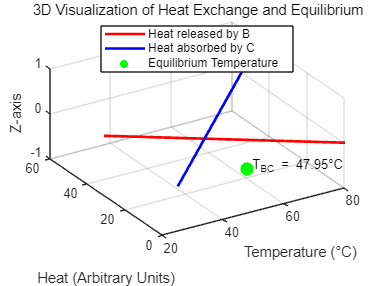

% 주어진 값들
T_B = 80; % 물질 B의 온도 (°C)
T_C = 25; % 물질 C의 온도 (°C)
C_B_div_C_C = 0.716; % 물질 B와 C의 비열비

% 열평형 온도 재계산
T_BC_correct = (C_B_div_C_C * T_B + T_C) / (1 + C_B_div_C_C);

% T_BC를 나타내기 위한 온도 범위 생성
T_BC_range = linspace(T_C, T_B, 100);

% 비선형 함수: 열평형 온도 방정식의 비율로 표현
Q_B = C_B_div_C_C * (T_B - T_BC_range); % B의 열량 변화
Q_C = (T_BC_range - T_C); % C의 열량 변화

% 3D 그래프 그리기
figure;
hold on;
grid on;

% 물질 B의 열량 변화
plot3(T_BC_range, Q_B, zeros(size(T_BC_range)), 'r-', 'LineWidth', 2);
% 물질 C의 열량 변화
plot3(T_BC_range, Q_C, zeros(size(T_BC_range)), 'b-', 'LineWidth', 2);

% 열평형 지점 표시
scatter3(T_BC_correct, 0, 0, 100, 'g', 'filled');
text(T_BC_correct + 1, 0, 0, sprintf('T_{BC} = %.2f°C', T_BC_correct), 'Color', 'k');

% 축 레이블 및 제목 설정
xlabel('Temperature (°C)');
ylabel('Heat (Arbitrary Units)');
zlabel('Z-axis');
title('3D Visualization of Heat Exchange and Equilibrium');
legend('Heat released by B', 'Heat absorbed by C', 'Equilibrium Temperature', 'Location', 'Best');

view(3);
hold off;

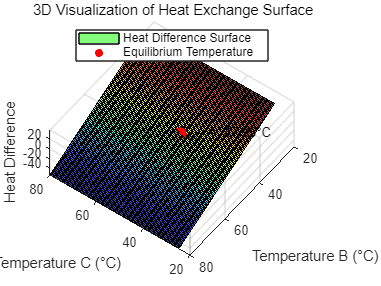

% 주어진 값들
T_B = 80; % 물질 B의 온도 (°C)
T_C = 25; % 물질 C의 온도 (°C)
C_B_div_C_C = 0.716; % 물질 B와 C의 비열비

% 열평형 온도 재계산
T_BC_correct = (C_B_div_C_C * T_B + T_C) / (1 + C_B_div_C_C);

% T_BC를 나타내기 위한 온도 범위 생성
T_BC_range = linspace(T_C, T_B, 100);

% 비선형 함수: 열평형 온도 방정식의 비율로 표현
Q_B = C_B_div_C_C * (T_B - T_BC_range); % B의 열량 변화
Q_C = (T_BC_range - T_C); % C의 열량 변화
HeatDifference = Q_B - Q_C; % 열량 차이

% 3D 그래프 그리기
figure;
hold on;
grid on;

% X, Y를 위한 메쉬 그리드 생성
[X, Y] = meshgrid(T_BC_range, T_BC_range);
Z = C_B_div_C_C * (T_B - X) - (X - T_C); % 열량 차이의 표면

% 표면 그래프 그리기
surf(X, Y, Z, 'FaceAlpha', 0.7);
colormap('jet'); % 기본적으로 사용 가능한 컬러맵을 사용

% 열평형 지점 표시
scatter3(T_BC_correct, T_BC_correct, 0, 100, 'r', 'filled');
text(T_BC_correct + 1, T_BC_correct, 0, sprintf('T_{BC} = %.2f°C', T_BC_correct), 'Color', 'k');

% 축 레이블 및 제목 설정
xlabel('Temperature B (°C)');
ylabel('Temperature C (°C)');
zlabel('Heat Difference');
title('3D Visualization of Heat Exchange Surface');
legend('Heat Difference Surface', 'Equilibrium Temperature', 'Location', 'Best');

% 뷰 설정
view(3);
hold off;